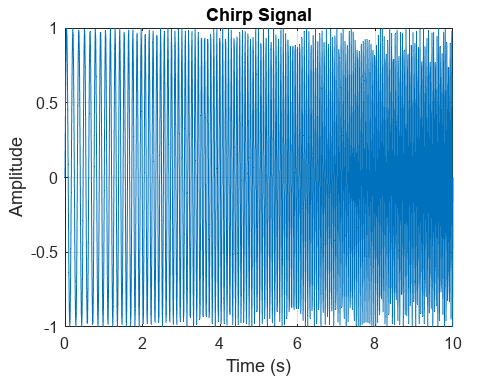

%11

duration = 10;              
sampling_rate = 100;     
t = linspace(0, duration, duration * sampling_rate);  
f_start = 6;                
f_end = 15;                 
F = linspace(f_start, f_end, duration * sampling_rate); 
x=sin(2*pi*F.*t);
figure;
plot(t, x);
title('Chirp Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

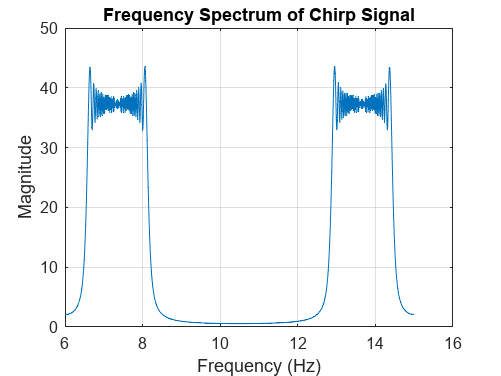


%12
N = length(x);                  
X = fft(x);                     
X_magnitude = abs(X);           
frequencies = (0:N-1) * (sampling_rate / N);  
figure;
plot(F, X_magnitude);
title('Frequency Spectrum of Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

[max_magnitude, max_index] = max(X_magnitude);
dominant_frequency = frequencies(max_index);
fprintf('Dominant frequency component: %.2f Hz\n', dominant_frequency);

Dominant frequency component: 22.90 Hz


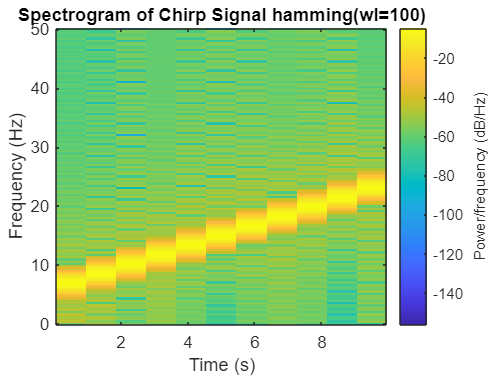


%13

window_length1 = 100;  
overlap = 10;         
figure;

%100
spectrogram(x, hamming(window_length1), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hamming(wl=100)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

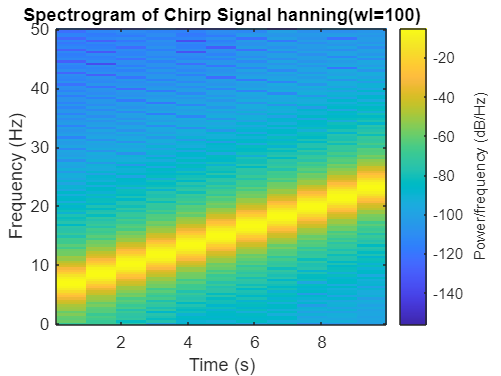

spectrogram(x, hanning(window_length1), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hanning(wl=100)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

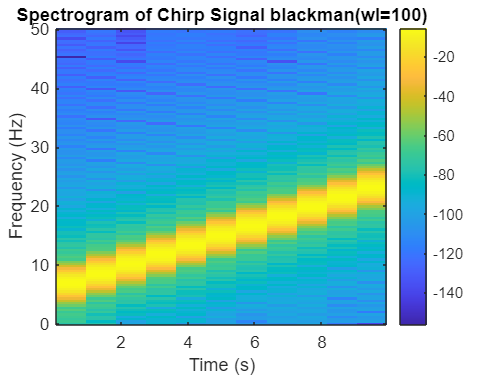

spectrogram(x, blackman(window_length1), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal blackman(wl=100)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

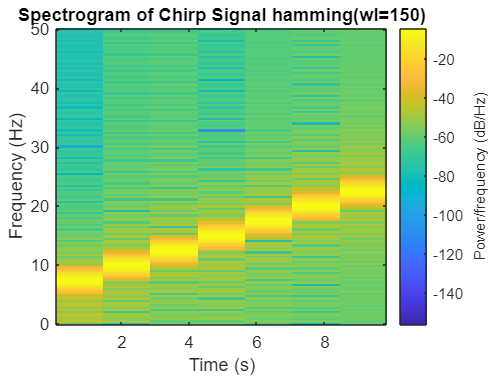


%150
window_length2 = 150;  
spectrogram(x, hamming(window_length2), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hamming(wl=150)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

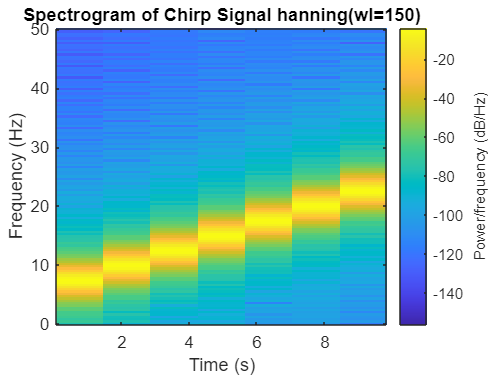

spectrogram(x, hanning(window_length2), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hanning(wl=150)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

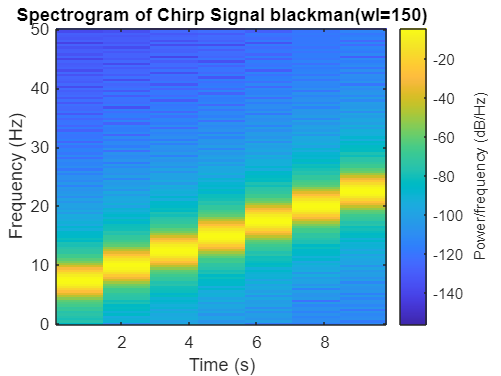

spectrogram(x, blackman(window_length2), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal blackman(wl=150)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

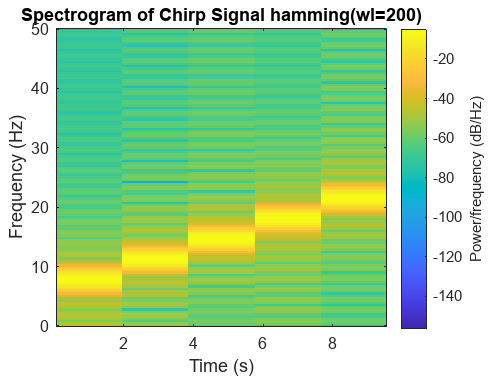


%200
window_length3 = 200; 
spectrogram(x, hamming(window_length3), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hamming(wl=200)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

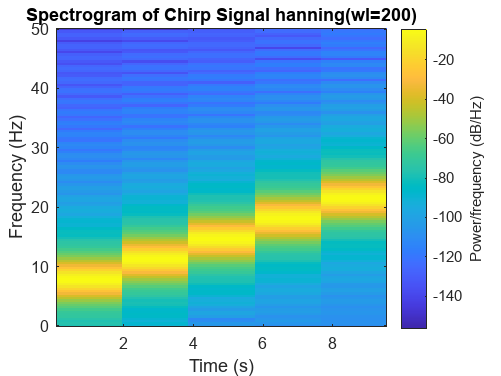

spectrogram(x, hanning(window_length3), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal hanning(wl=200)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

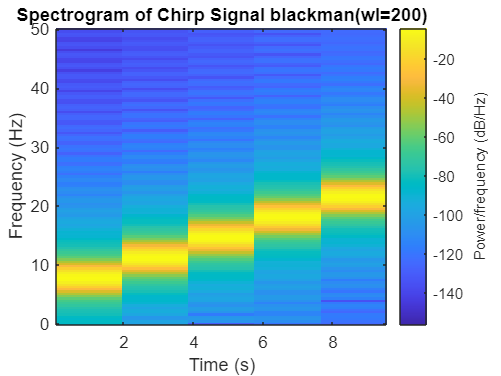

spectrogram(x, blackman(window_length3), overlap, [], sampling_rate, 'yaxis');
title('Spectrogram of Chirp Signal blackman(wl=200)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

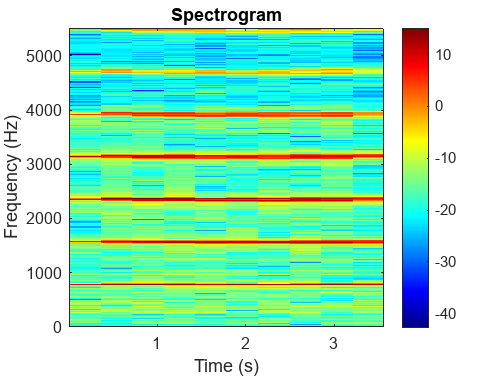

% Example: Load an audio file
[y1, Fs] = audioread('instru2.wav');
window_length = 3950;  % Window size in samples
overlap = 20;         % Overlap between consecutive windows in samples
nfft = 3950;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y1, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram');
colorbar;  % Add a colorbar to show magnitude values

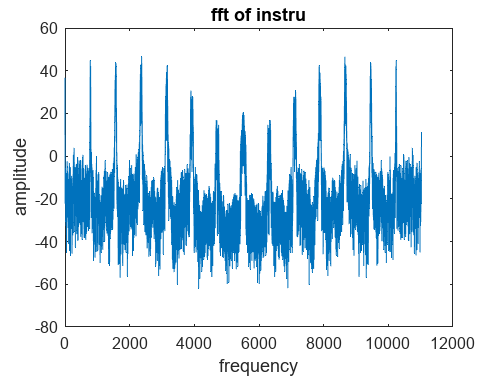


figure;
fft_instru=abs(fft(y1));
freqs = (0:length(fft(y1))-1)*Fs/length(fft(y1)) ;
plot(freqs,20*log10(fft_instru))
title("fft of instru")
xlabel("frequency")
ylabel("amplitude")

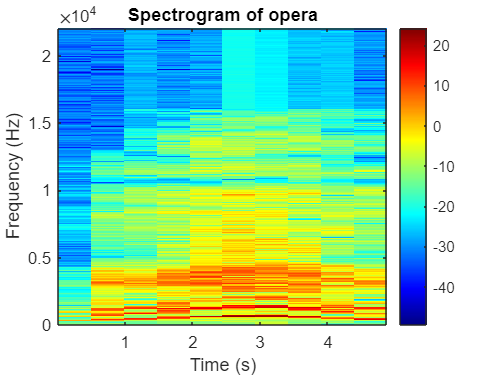


%22

[y, Fs] = audioread('Opera.wav');
window_length = 22000; 
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 22000;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of opera');
colorbar; 

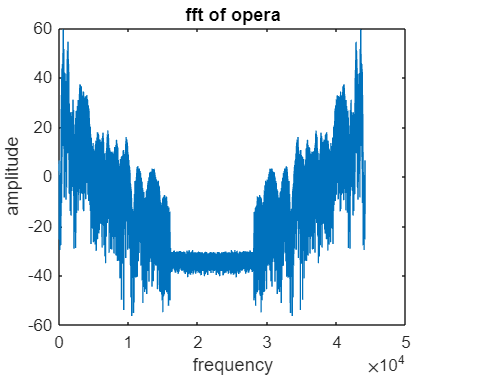

fft_opera=abs(fft(y));
freqs1 = (0:length(fft(y))-1)*Fs/length(fft(y)) ;
plot(freqs1,20*log10(fft_opera))
title("fft of opera")
xlabel("frequency")
ylabel("amplitude")% Add a colorbar to show magnitude values

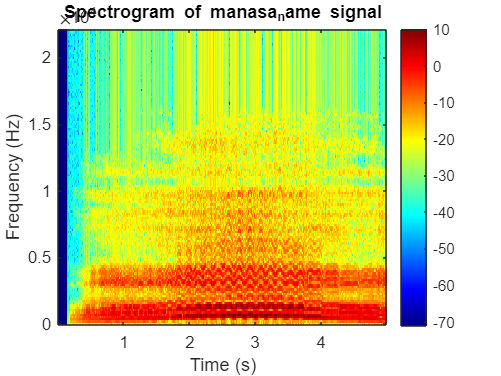

%3 Load the .wav file
[audio_data, sample_rate] = audioread('manasa.wav');
% Resample to 4000 Hz if necessary
target_sample_rate = 4000;
if sample_rate ~= target_sample_rate
    audio_data = resample(audio_data, target_sample_rate, sample_rate);
    sample_rate = target_sample_rate;
end
% Parameters for the spectrogram
window_size = 256; % Size of the analysis window
overlap = 128;    % Overlap between windows
nfft=256;
[S, f, t] = spectrogram(y, hamming(window_size), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of manasa_name signal');
colorbar;